im = imread("peppers.png"); 


pep_r = im(:,:,1);
pep_g = im(:,:,2);
pep_b = im(:,:,3);



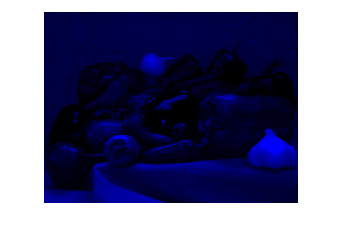

im_b = im;
im_b(:,:,1) = pep_r * 0;
im_b(:,:,2) = pep_g * 0;

imshow(im_b);

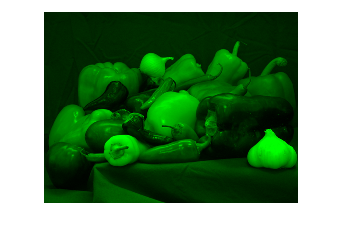



im_g = im;
im_g(:,:,1) = pep_r * 0;
im_g(:,:,3) = pep_b * 0;

imshow(im_g);

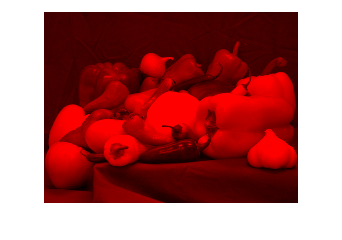


im_r = im;
im_r(:,:,2) = pep_g * 0;
im_r(:,:,3) = pep_b * 0;

imshow(im_r);

fig = montage({pep_r,pep_g,pep_b, im_r,im_g,im_b}, 'Size',[2,3])

fig =   Image with properties:

           CData: [768×1536×3 uint8]
    CDataMapping: 'direct'

  Show all properties


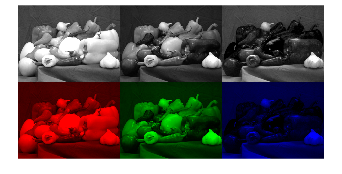


saveas(fig,"peppers_RGB.png");

hist_r = histogram(pep_r,'BinEdges', 0:256, 'FaceColor','red'); hold on; 
hist_g = histogram(pep_g,'BinEdges', 0:256, 'FaceColor','green'); hold on; 
hist_b = histogram(pep_b,'BinEdges', 0:256, 'FaceColor','blue'); hold off; 
f = gcf; 
saveas(f, "hist_RGB_peppers.png")

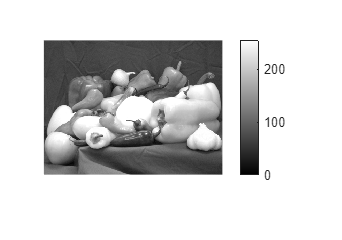


imshow(pep_r); colorbar; 

saveas(gcf, "pep_r_colorbar.png");



imshow(pep_r); colormap("autumn"); colorbar;
saveas(gcf, "pep_r_colorbar2.png");
imshow(pep_r); colormap("winter"); colorbar;
saveas(gcf, "pep_r_colorbar3.png");

